## 第4章  神经网络遗传算法函数极值寻优

%% 清空环境变量
clc
clear

## 训练数据预测数据提取及归一化

%下载输入输出数据
load data1 input output

%从1到2000间随机排序
k=rand(1,4000);
[m,n]=sort(k);

%找出训练数据和预测数据
input_train=input(n(1:3900),:)';
output_train=output(n(1:3900),:)';
input_test=input(n(3901:4000),:)';
output_test=output(n(3901:4000),:)';

%选连样本输入输出数据归一化
[inputn,inputps]=mapminmax(input_train);
[outputn,outputps]=mapminmax(output_train);

## BP网络训练

%%初始化网络结构
net=newff(inputn,outputn,5);

net.trainParam.epochs=100;
net.trainParam.lr=0.1;
net.trainParam.goal=0.0000004;

%网络训练
net=train(net,inputn,outputn);

%% BP网络预测
%预测数据归一化
inputn_test=mapminmax('apply',input_test,inputps);
 
%网络预测输出
an=sim(net,inputn_test);
 
%网络输出反归一化
BPoutput=mapminmax('reverse',an,outputps);

## 结果分析

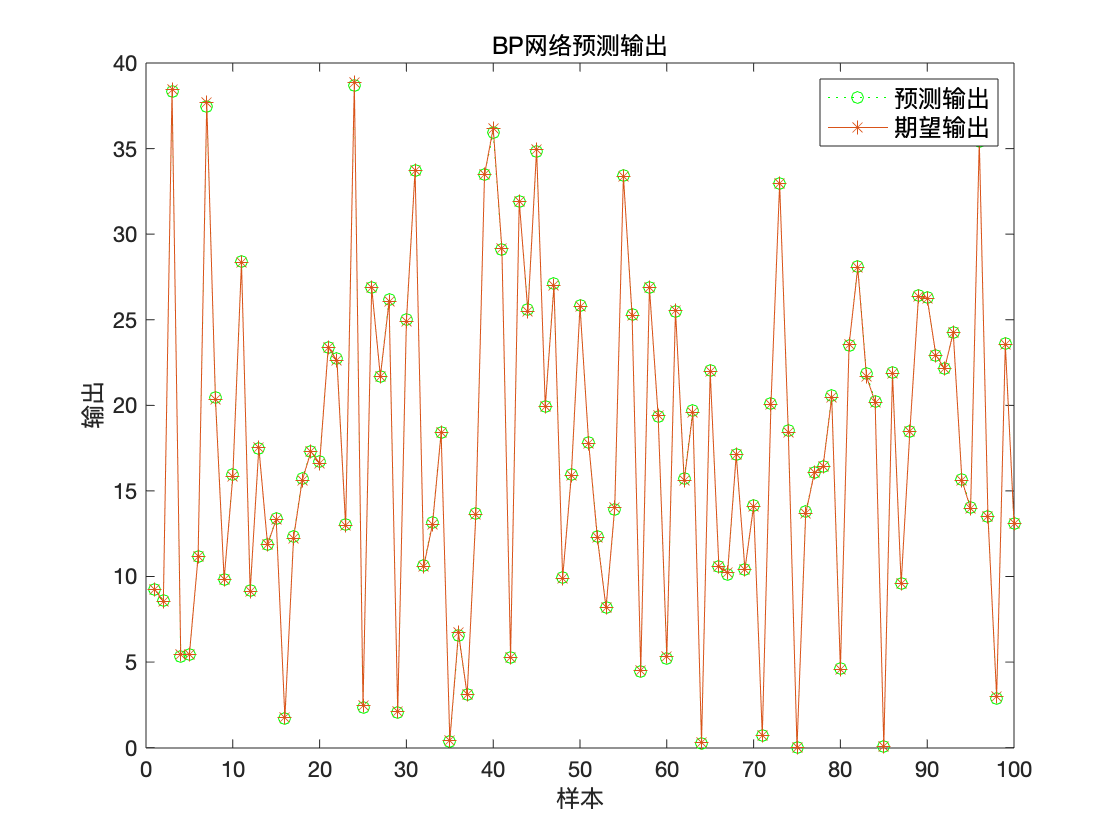

figure(1)
plot(BPoutput,':og')
hold on
plot(output_test,'-*');
legend('预测输出','期望输出','fontsize',12)
title('BP网络预测输出','fontsize',12)
xlabel('样本','fontsize',12)
ylabel('输出','fontsize',12)

### 预测误差

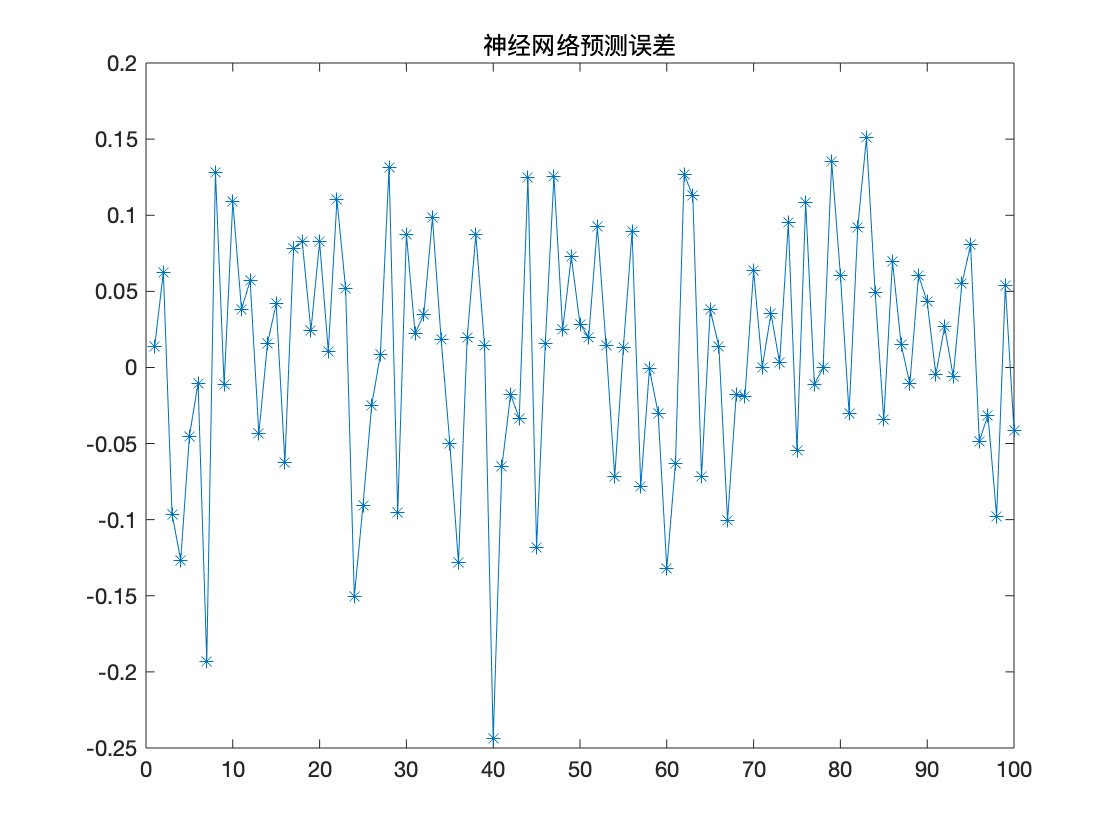

error=BPoutput-output_test;

figure(2)
plot(error,'-*')
title('神经网络预测误差')

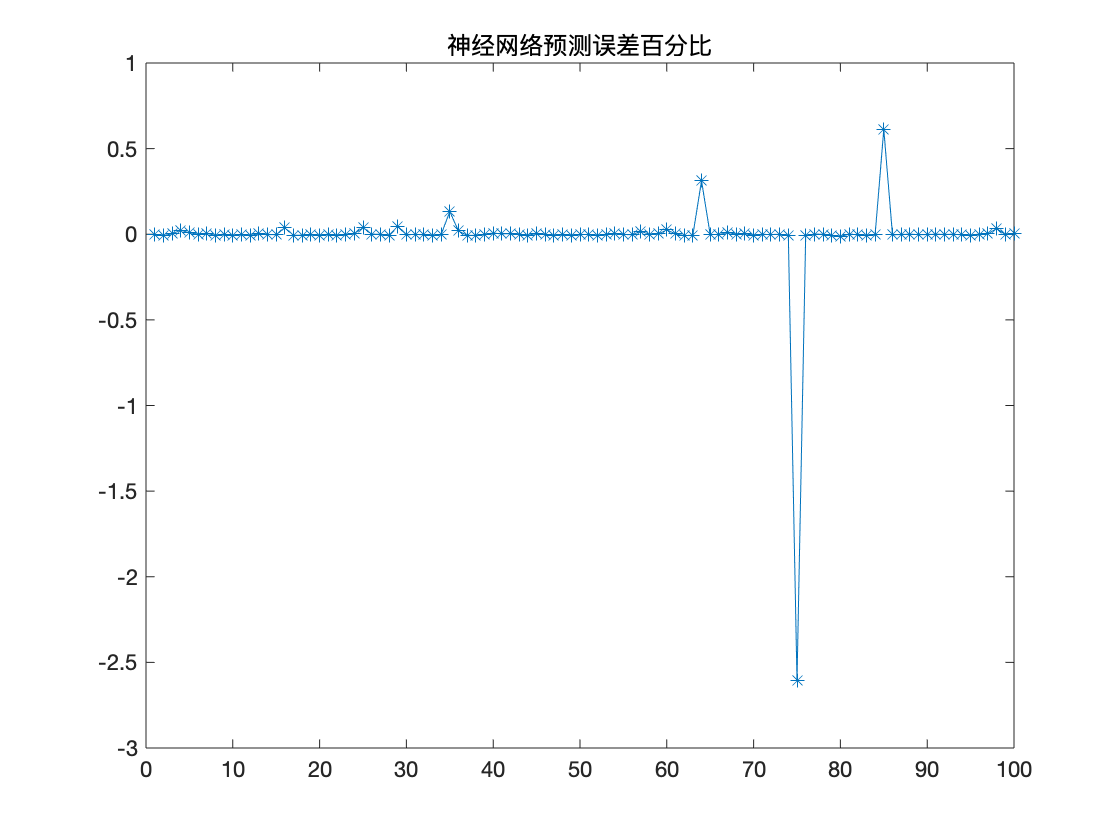

figure(3)
plot((output_test-BPoutput)./BPoutput,'-*');
title('神经网络预测误差百分比')

errorsum=sum(abs(error))

errorsum = 6.1016

save data net inputps outputps  %将net inputps outputps 存在data.mat中